# shade

二维绘图后填充

### 使用方法

`plot怎么用shade就怎么用`

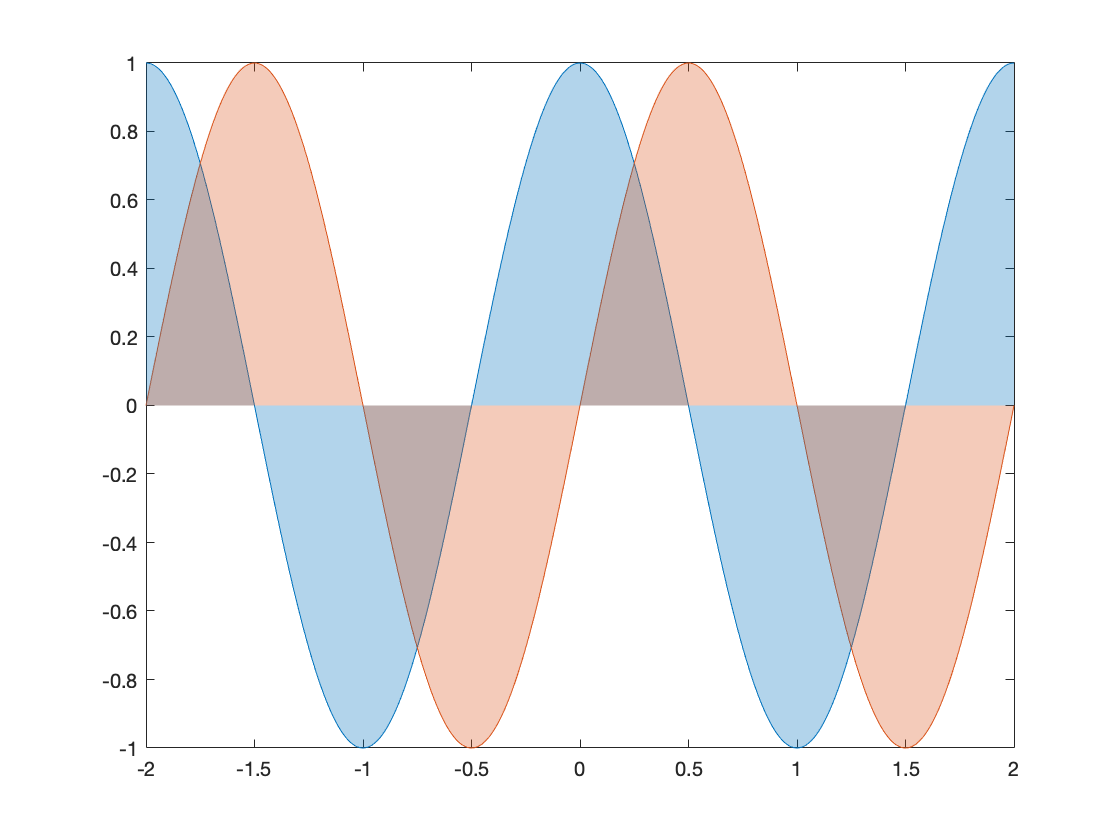

x = -2:0.01:2;
y1 = cos(pi*x);
y2 = sin(pi*x);

shade(x,y1,x,y2)

`shade` 会在画完图之后填充曲线和x轴之间的区域

### 通用绘图选项

像对plot那样指定任何plot选项

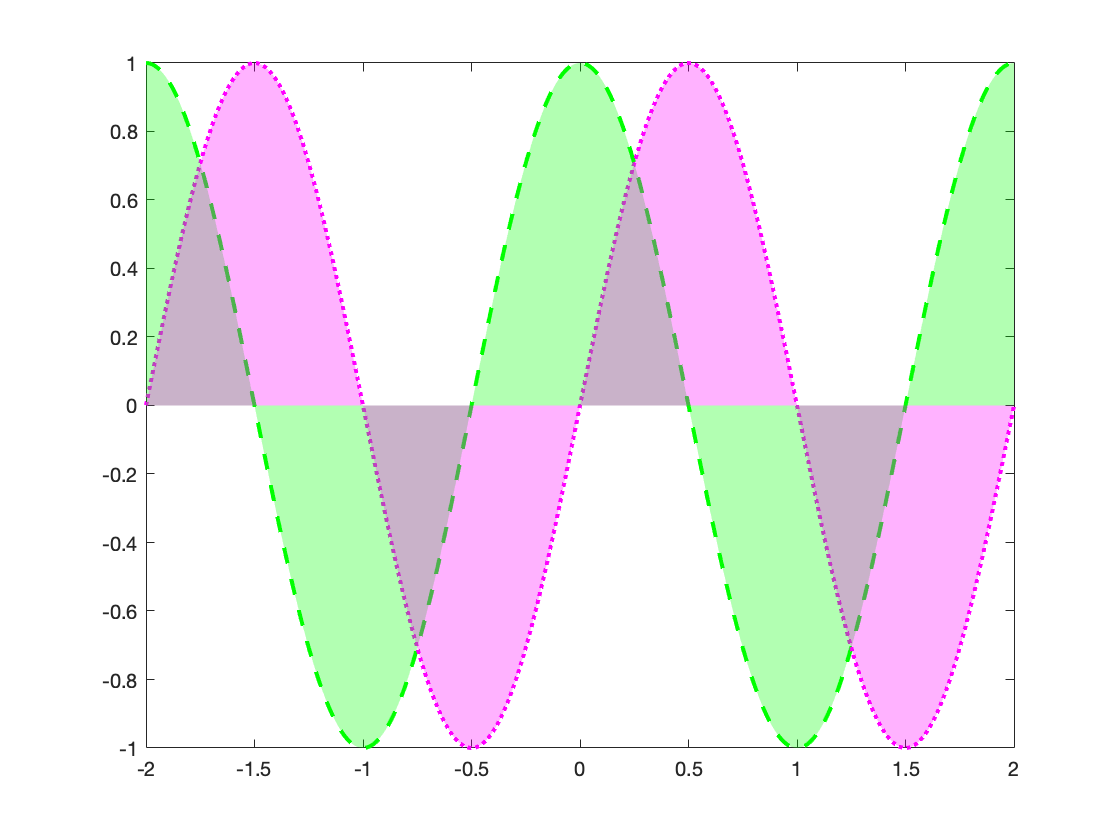

shade(x,y1,'--g',x,y2,':m','LineWidth',2)

还可以在指定axes对象上创建绘图

### **填充选项**

#### 填充类型

参数FillType可用于指定应该填充哪些区域。是一个两列矩阵，其中每行的左列和右列是指定填充区域的上界和下界的索引。

要填充曲线1和曲线2之间的区域，其中曲线1是上限，曲线2是下限，这样指定：

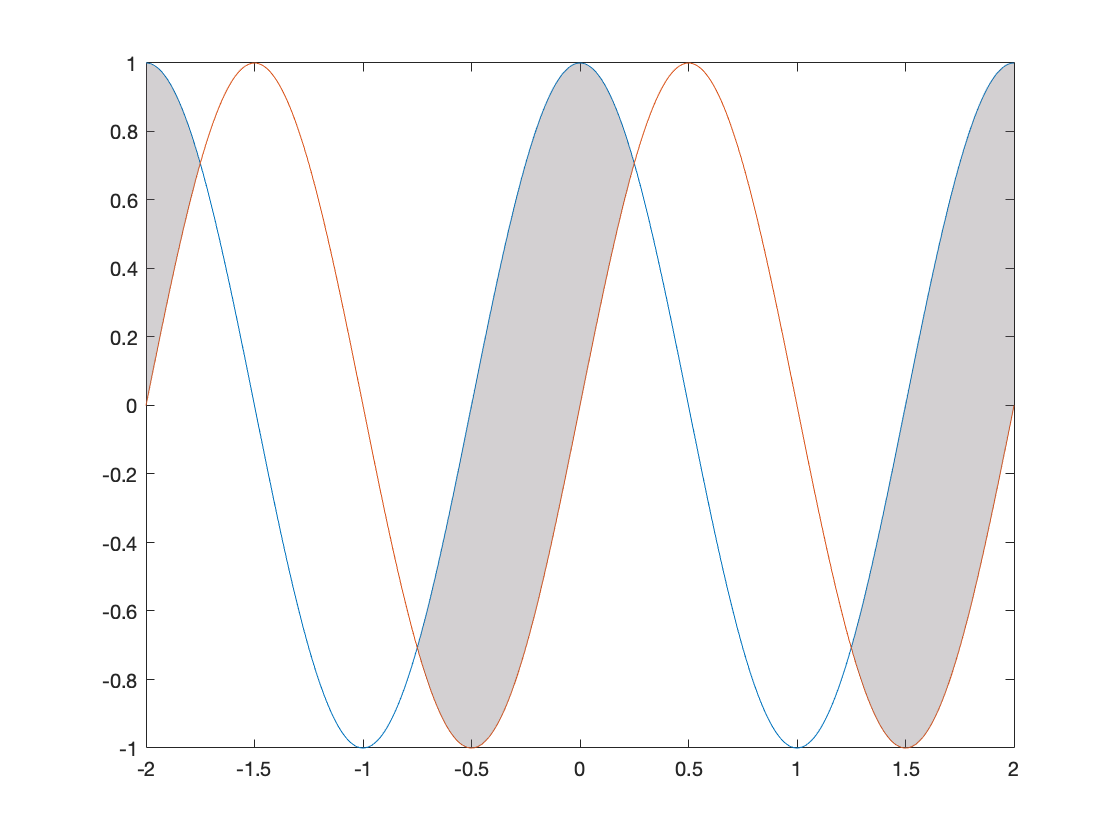

shade(x,y1,x,y2,'FillType',[1 2])

可以指定多行来填充多个区域，这样指定:

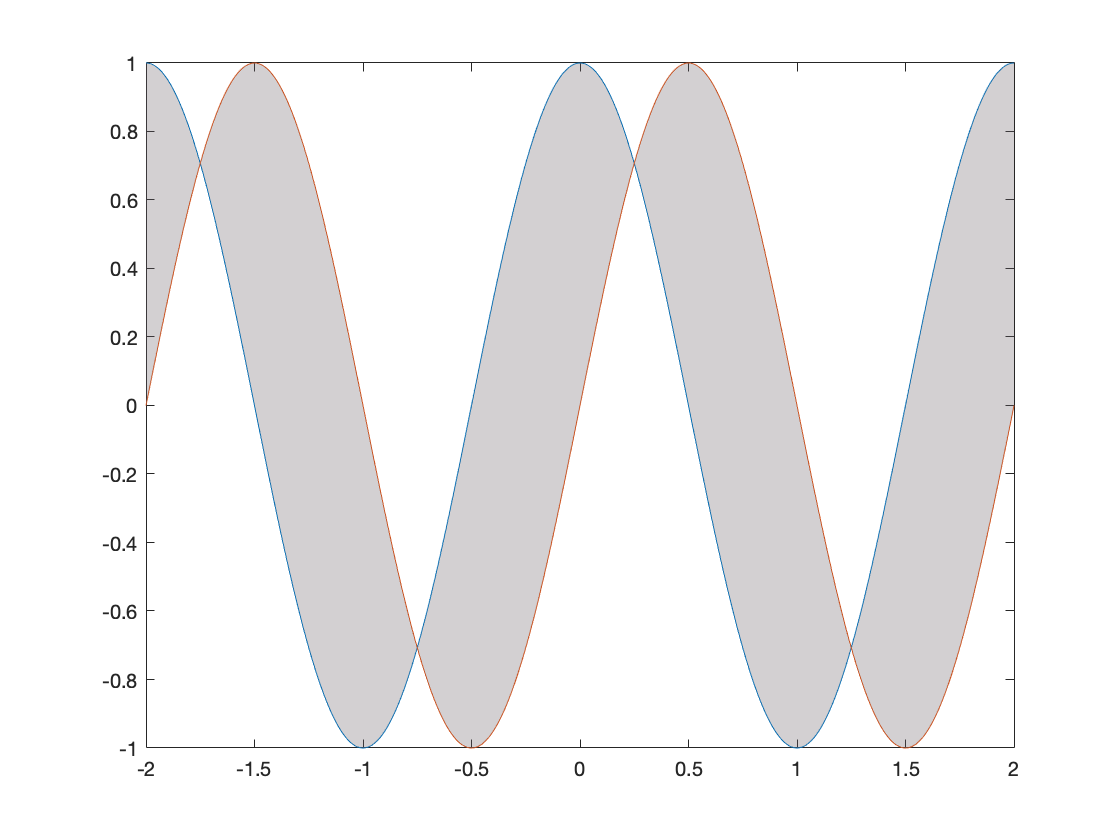

shade(x,y1,x,y2,'FillType',[1 2;2 1])

值0表示x轴。填充到x轴，仅用于曲线1：

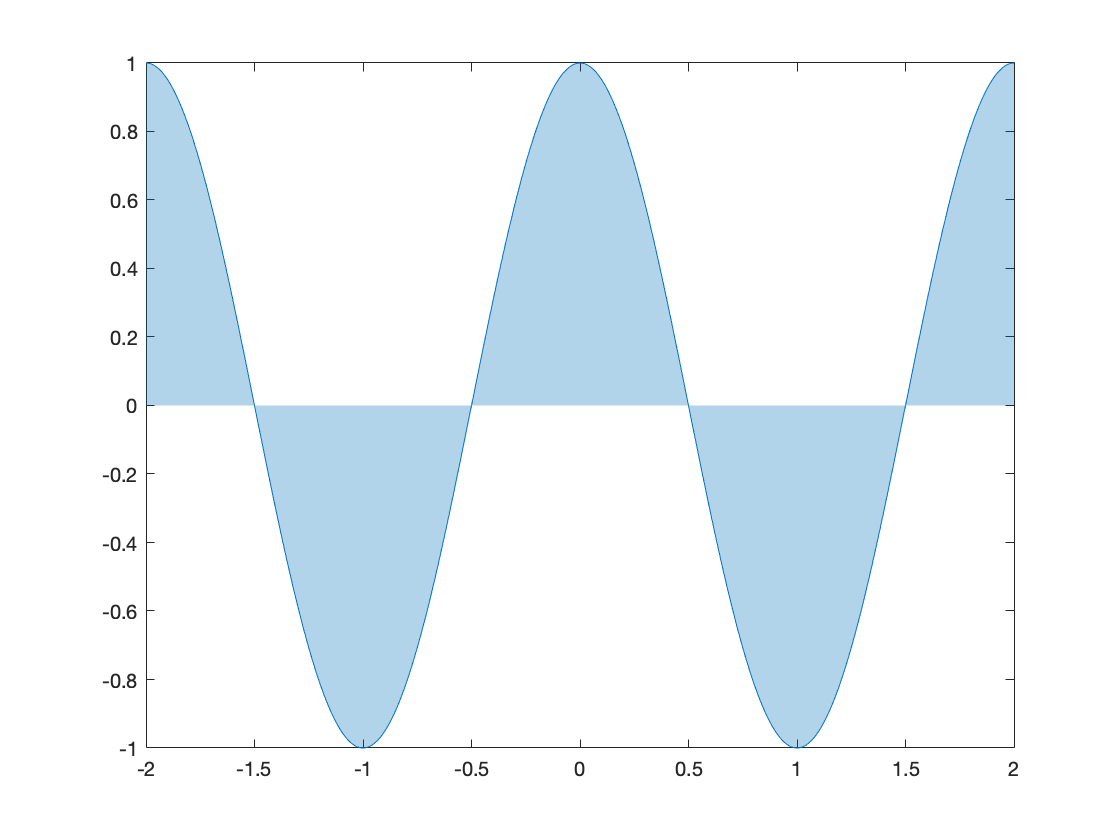

shade(x,y1,'FillType',[1 0;0 1])

cell数组也可以用于指定填充类型。在这种情况下，除了索引之外，还可以使用底部和顶部。要填充到底部，这样指定：

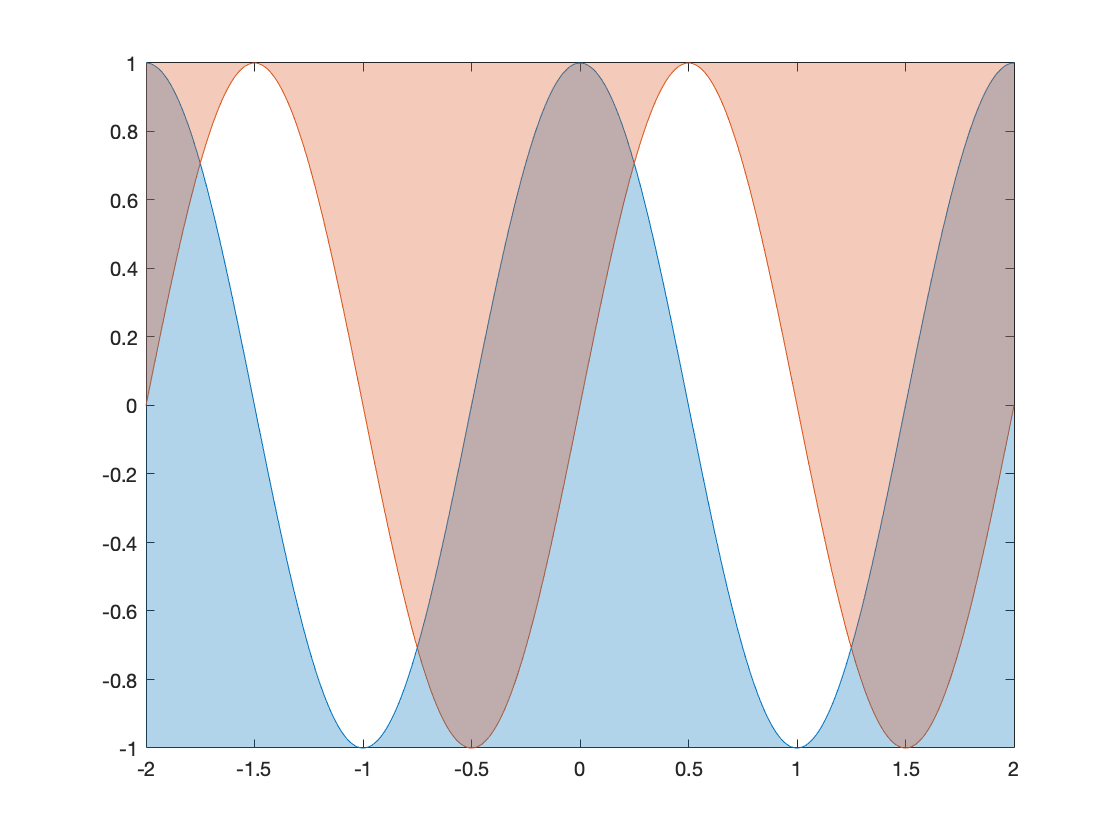

shade(x,y1,x,y2,'FillType',{1 'bottom';'top' 2})

注意，底部只能用于第二列，而顶部只能用于第一列。

#### 填充颜色

使用绘图选项更改线条颜色，填充颜色将自动适应以反映相应线的颜色。

但是，填充颜色也可以使用参数FillColor独立地更改。这是一个具有与FillType相同行数的三列矩阵，其中每行是一个RGB三元组（如果FillType不是手动指定的，它有2*N行，其中N是绘图中的行数）

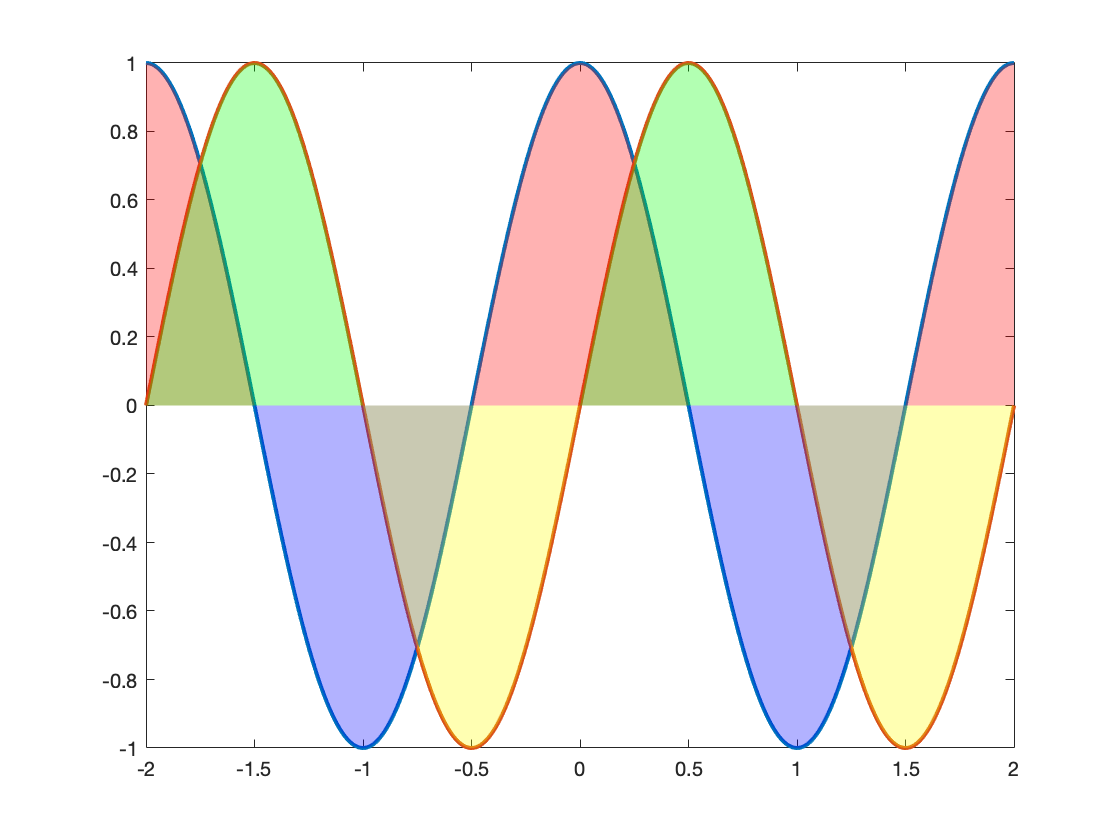

shade(x,y1,x,y2,'LineWidth',2,'FillColor',[1 0 0;0 0 1;0 1 0;1 1 0])

如果只指定了一个RGB三元组，则所有区域都使用相同的颜色：

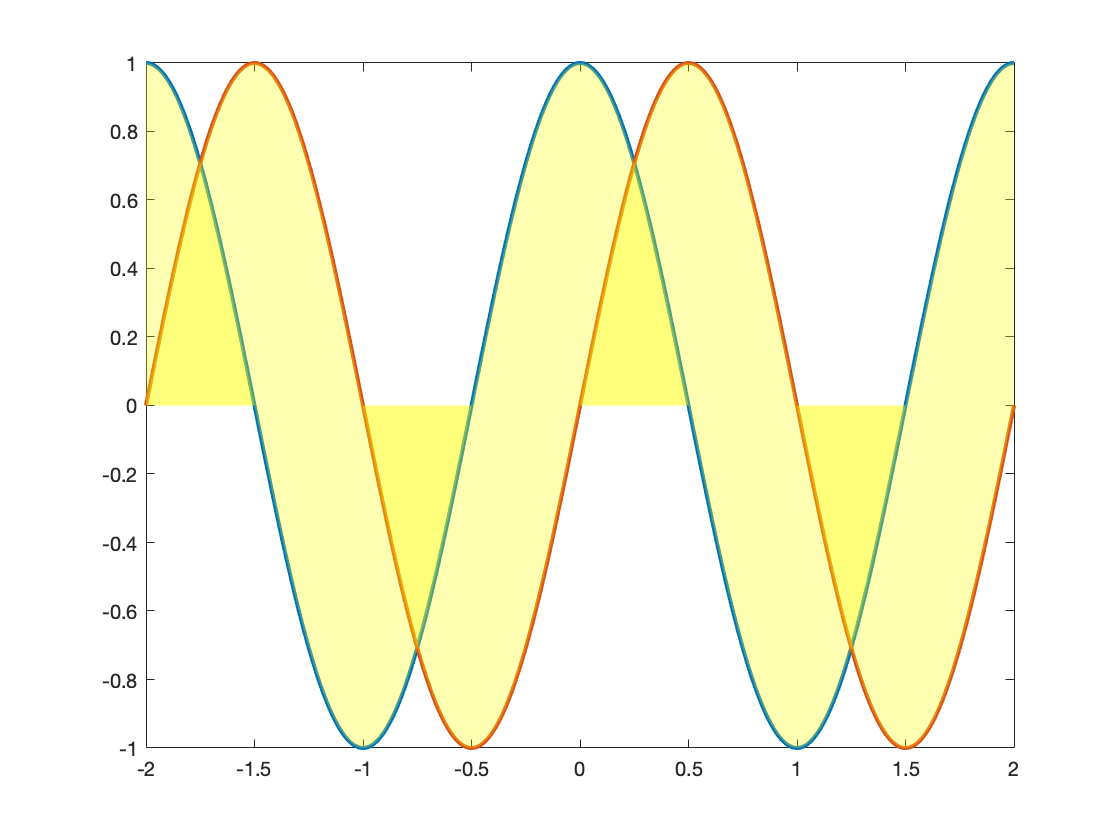

shade(x,y1,x,y2,'LineWidth',2,'FillColor',[1 1 0])

`FillColor也可以使用cell数组指定，在这种情况下，颜色名称也可以用说明符。cell数组应该具有与FillType矩阵或单元格数组中的行相同的行，或者只有一个行，在这种情况下，所有区域都使用相同的颜色。颜色名称和RGB三元组可以组合在一个单元格数组中。`

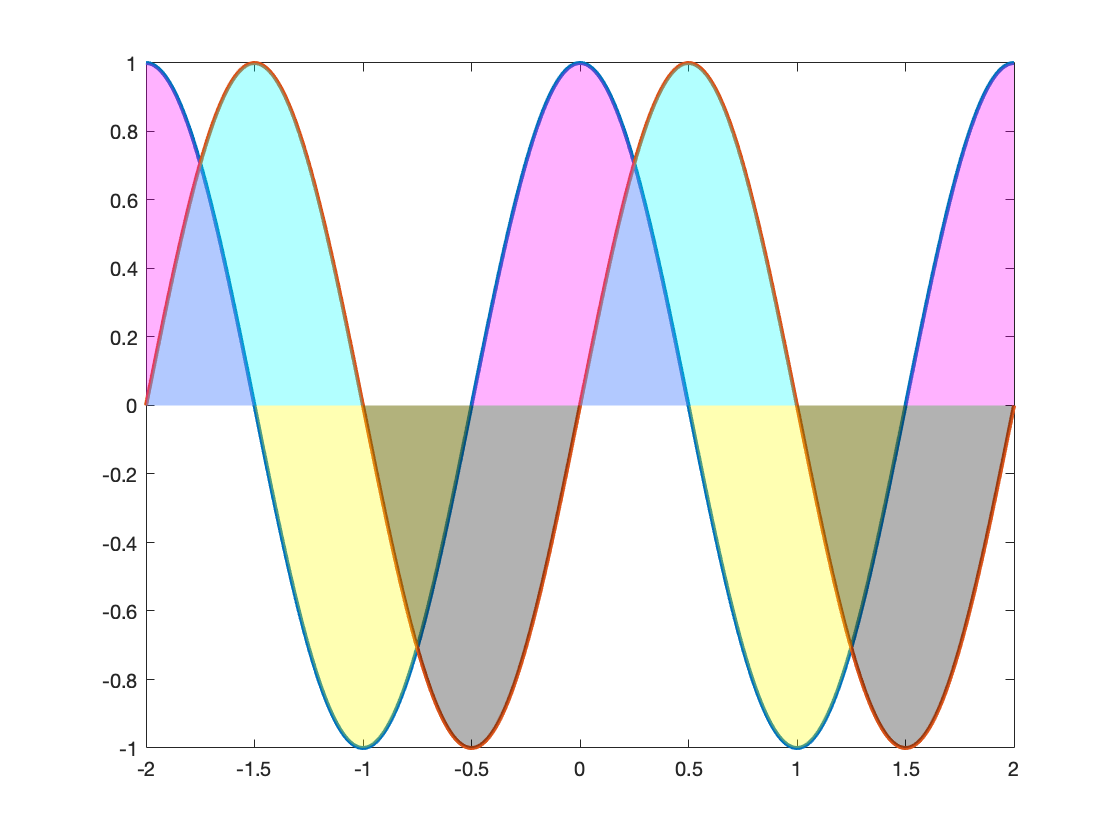

shade(x,y1,x,y2,'LineWidth',2,'FillColor',{'magenta','yellow','cyan','black'})

#### 填充透明度

`可以指定FillAlpha以改变填充区域的透明度。这个向量的行应该与FillType矩阵或单元格数组中的行一样多。或者，如果仅指定一个值，则所有区域都使用相同的alpha。`

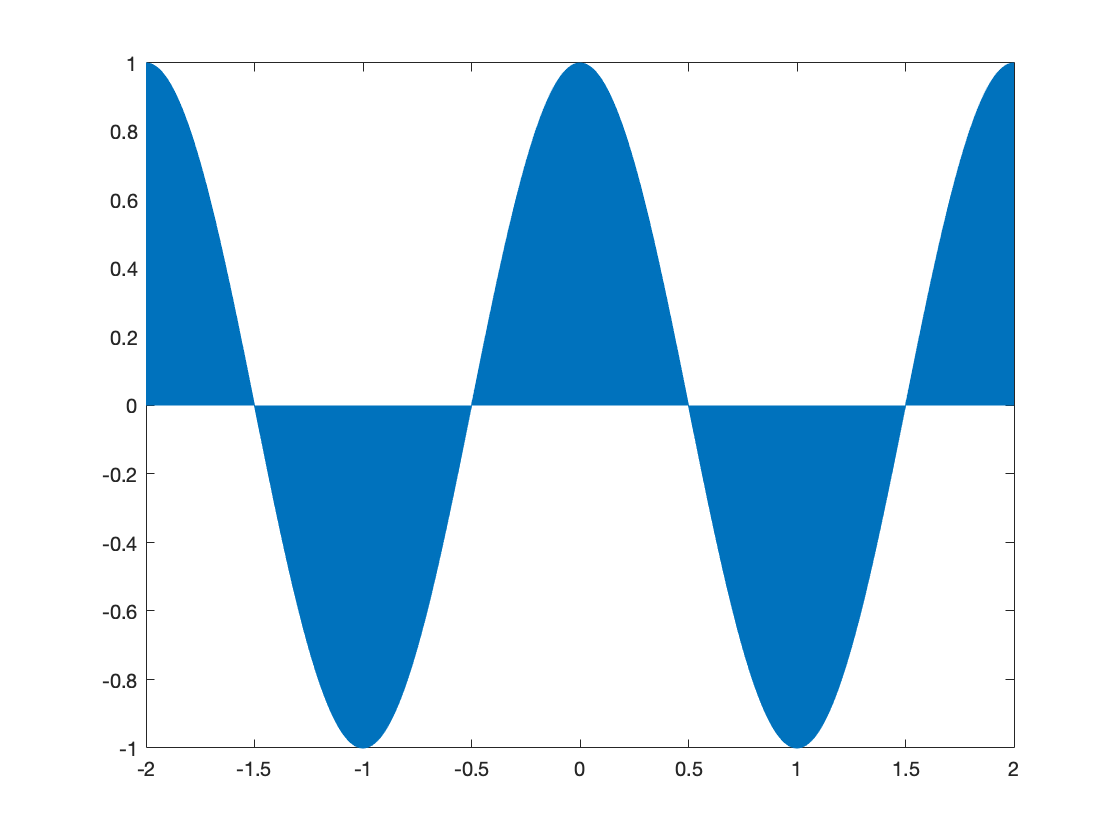

shade(x,y1,'FillAlpha',1)

### 输出

指定一个输出参数，以获取所有绘图对象的句柄数组，包括行和填充区域。可以在创建之后使用这些句柄来修改图形属性。

h =   6×1 graphics array:

  Line
  Line
  Patch
  Patch
  Patch
  Patch


h = shade(x,y1,x,y2)